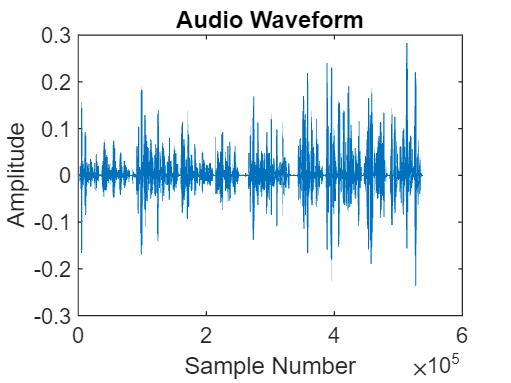

% Path to the .wav file for noise
aritificial_nonstat_noise = 'aritificial_nonstat_noise.wav';
Speech_shaped_noise = 'Speech_shaped_noise.wav';
babble_noise = 'babble_noise.wav';

% Path to the .wav file for clean speech
clean_speech = 'clean_speech.wav';
clean_speech_2 = 'clean_speech_2.wav';

% Read the audio file
[clean_speech, fs] = audioread(clean_speech);
[clean_speech_2, ~] = audioread(clean_speech_2);
[babble_noise, ~] = audioread(babble_noise);
[aritificial_nonstat_noise, ~] = audioread(aritificial_nonstat_noise);
[Speech_shaped_noise, ~] = audioread(Speech_shaped_noise);

% Play the sound
%sound(clean_speech, fs);

% Plot the sound wave
figure;
plot(clean_speech_2);
xlabel('Sample Number');
ylabel('Amplitude');
title('Audio Waveform');

% Ensure the noise is long enough
babble_noise = babble_noise(1:length(clean_speech_2));
Speech_shaped_noise = Speech_shaped_noise(1:length(clean_speech_2));
aritificial_nonstat_noise = aritificial_nonstat_noise(1:length(clean_speech_2));
clean_speech = clean_speech(1:length(clean_speech_2));

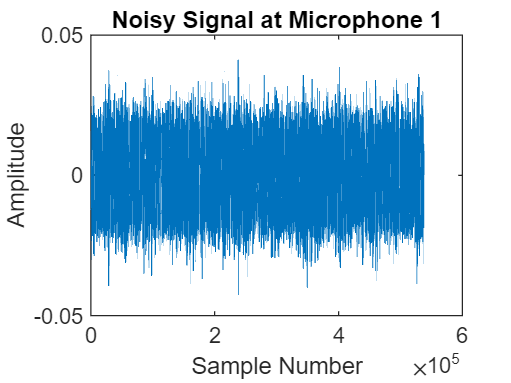

% This should contain h_inter1, h_inter2, h_inter3, h_inter4, h_target
load('impulse_responses.mat'); 

% Number of microphones and sources
num_mics = 4;
num_sources = 5;

% Define the sources (assuming these are already defined or loaded)
sources = {clean_speech, babble_noise, Speech_shaped_noise, aritificial_nonstat_noise, clean_speech_2};

% Initialize microphone signals
mic_signals = cell(num_mics, 1);
mic_noise = cell(num_mics, 1);
for mic = 1:num_mics
    mic_signals{mic} = zeros(length(clean_speech_2), 1); % Assuming clean_speech_2 determines the length
    mic_noise{mic} = zeros(length(clean_speech_2), 1);
end

% Define the impulse responses
% impulse_responses should be a cell array where each element is a 4x400 matrix
% containing impulse responses from each source to each microphone
impulse_responses = {h_inter1, h_inter2, h_inter3, h_inter4, h_target};

% Convolve each source with its corresponding impulse response and sum them

for mic = 1:num_mics
    for src = 1:num_sources
        h = impulse_responses{src}(mic, :); % Get impulse response for current source and microphone
        % Convolve source with impulse response and sum to microphone signal
        mic_signals{mic} = mic_signals{mic} + conv(sources{src}, h, 'same');
        if src < 5
            mic_noise{mic} = mic_noise{mic} + conv(sources{src}, h, 'same');
        end
    end
end

% Plot one of the noisy signals
figure;
plot(mic_signals{1}); % Plot signal from microphone 1 
xlabel('Sample Number');
ylabel('Amplitude');
title('Noisy Signal at Microphone 1');

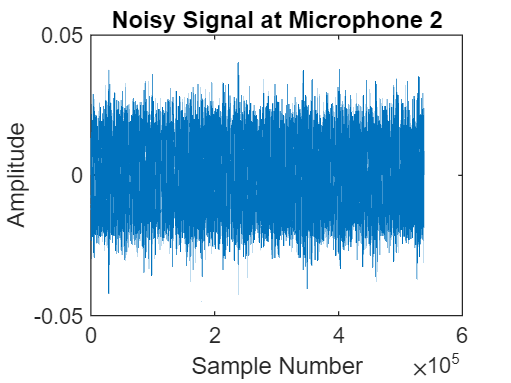



% Plot one of the noisy signals
figure;
plot(mic_signals{2}); % Plot signal from microphone 1 
xlabel('Sample Number');
ylabel('Amplitude');
title('Noisy Signal at Microphone 2');

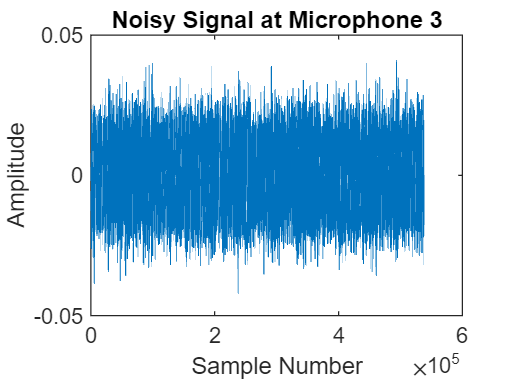



% Plot one of the noisy signals
figure;
plot(mic_signals{3}); % Plot signal from microphone 1 
xlabel('Sample Number');
ylabel('Amplitude');
title('Noisy Signal at Microphone 3');

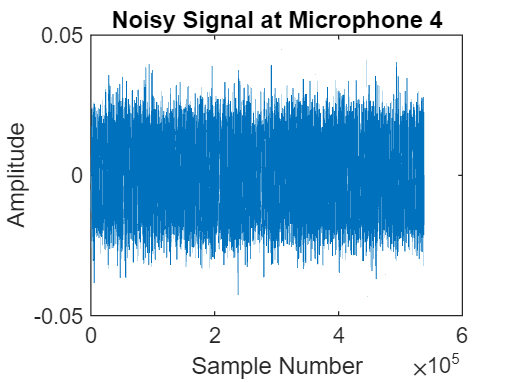



% Plot one of the noisy signals
figure;
plot(mic_signals{4}); % Plot signal from microphone 1 
xlabel('Sample Number');
ylabel('Amplitude');
title('Noisy Signal at Microphone 4');

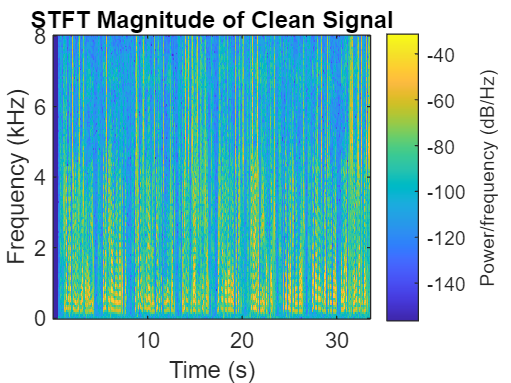

% Parameters for STFT
frame_size = round(0.02 * fs); % 20 ms frame size
overlap = round(0.01 * fs); % 50% overlap
window = hann(frame_size); % Hamming window

% Perform STFT on the clean signal
stft_signal_clean = stft(clean_speech, 'Window', window, 'OverlapLength', overlap, 'FFTLength', frame_size);

% Plot STFT magnitude of the clean signal
figure;
spectrogram(clean_speech, window, overlap, frame_size, fs, 'yaxis');
title('STFT Magnitude of Clean Signal');

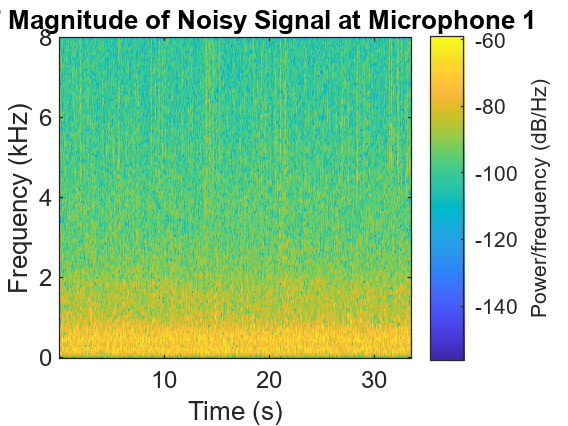


% Initialize a cell array to store STFT results
stft_signals = cell(num_mics, 1);

% Compute STFT for each microphone signal
for mic = 1:num_mics
    stft_signals{mic} = stft(mic_signals{mic}, 'Window', window, 'OverlapLength', overlap, 'FFTLength', frame_size);
end

% Determine the size of the STFT results
[num_freq_bins, num_time_frames] = size(stft_signals{1});

% Initialize a 3D tensor to store the STFT results for all microphones
stft_signals_tensor = zeros(num_freq_bins, num_time_frames, num_mics);

% Populate the 3D tensor with the STFT results
% stft_signals_tensor is a tensor with the stft of all microphones
for mic = 1:num_mics
    stft_signals_tensor(:, :, mic) = stft_signals{mic};
end


% Plot STFT magnitude of the first microphone signal (optional)
figure;
spectrogram(mic_signals{2}, window, overlap, frame_size, fs, 'yaxis');
title('STFT Magnitude of Noisy Signal at Microphone 1');

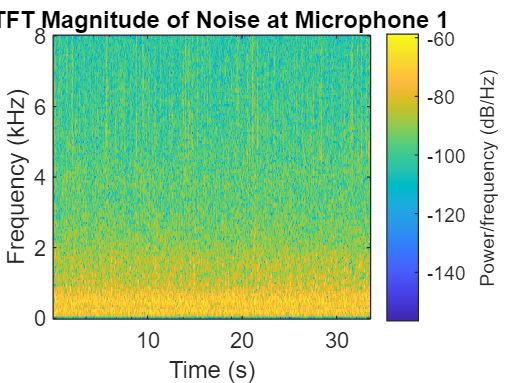

% Initialize a cell array to store STFT results
stft_noise = cell(num_mics, 1);

% Compute STFT for each microphone signal
for mic = 1:num_mics
    stft_noise{mic} = stft(mic_noise{mic}, 'Window', window, 'OverlapLength', overlap, 'FFTLength', frame_size);
end

% Initialize a 3D tensor to store the STFT results for all microphones
stft_noise_tensor = zeros(num_freq_bins, num_time_frames, num_mics);

% Populate the 3D tensor with the STFT results
% stft_signals_tensor is a tensor with the stft of all microphones
for mic = 1:num_mics
    stft_noise_tensor(:, :, mic) = stft_noise{mic};
end

% Plot STFT magnitude of the first microphone signal (optional)
figure;
spectrogram(mic_noise{2}, window, overlap, frame_size, fs, 'yaxis');
title('STFT Magnitude of Noise at Microphone 1');

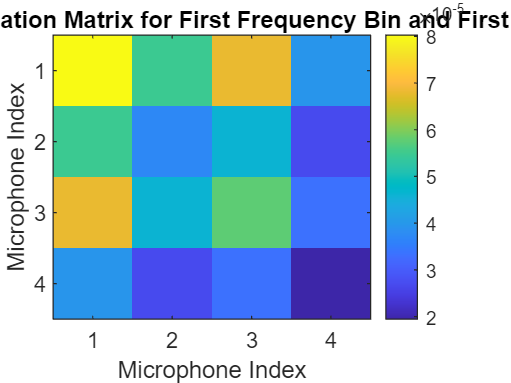

% Initialize a 4D tensor to store the correlation matrices for each frequency bin
Rx = zeros(num_freq_bins, num_mics, num_mics, num_time_frames);

% Initialize the first correlation matrix (all zeros)
Rx_prev = zeros(num_mics, num_mics);
alpha = 0.8;

% Compute the spatial correlation matrix for each frequency bin and time frame
for f = 1:num_freq_bins
    Rx_prev = zeros(num_mics,num_mics);
    for t = 1:num_time_frames
        
        % Extract the STFT signals for all microphones at a specific frequency bin and time frame
        X_ft = squeeze(stft_signals_tensor(f, t, :));
        
        % Compute the correlation matrix
        Variable = X_ft * X_ft';

        % Update the correlation matrix using the recursive formula
        Rx_curr = alpha * Rx_prev + (1 - alpha) * Variable;
        
        % Store the current correlation matrix
        Rx(f, :, :, t) = Rx_curr;
        
        % Update Rx_prev for the next time frame
        Rx_prev = Rx_curr;
    end
end

% Example: Plot the magnitude of the correlation matrix for the first frequency bin and first time frame
figure;
imagesc(abs(squeeze(Rx(1, :, :, 1))));
colorbar;
title('Magnitude of Correlation Matrix for First Frequency Bin and First Time Frame');
xlabel('Microphone Index');
ylabel('Microphone Index');

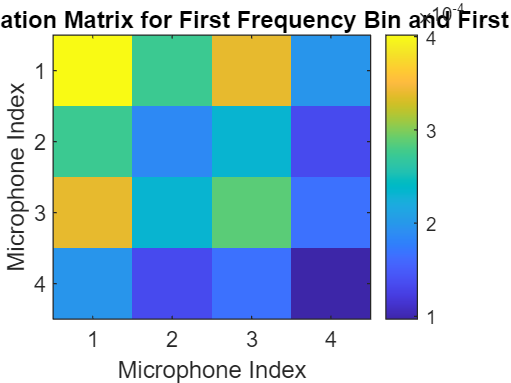

% Assume stft_noise_tensor is provided and has dimensions (num_freq_bins, num_time_frames, num_mics)
[num_freq_bins, num_time_frames, num_mics] = size(stft_noise_tensor);

% Initialize the 4D tensor to store the noise correlation matrices
Rn = zeros(num_freq_bins, num_mics, num_mics, num_time_frames);

% Compute the correlation matrices
for f = 1:num_freq_bins
    for t = 1:num_time_frames
        % Extract the noise data for all microphones at the given frequency bin and time frame
        noise_data = squeeze(stft_noise_tensor(f, t, :));  % This will be a vector of length num_mics
        
        % Compute the correlation matrix for this frequency bin and time frame
        Rn(f, :, :, t) = noise_data * noise_data';  % This is the outer product of the noise_data vector
    end
end

figure;
imagesc(abs(squeeze(Rn(1, :, :, 1))));
colorbar;
title('Magnitude of Correlation Matrix for First Frequency Bin and First Time Frame');
xlabel('Microphone Index');
ylabel('Microphone Index');

sigma_sn = zeros(num_freq_bins, num_time_frames);
epsilon = 1e-4;
for f = 1:num_freq_bins
    for t = 1:num_time_frames
        Rx_temp = squeeze(Rx(f, :, :, t));
        Rn_temp = squeeze(Rn(f, :, :, t));
        [V,D]=eig(Rx_temp,Rn_temp + epsilon* eye(num_mics));
        [eigvals,sidx] = sort(diag(D),'descend');
        U = V(:,sidx);
        Q = inv(U');
        U1 = U(:,1);
        Q1 = Q(:,1);
        sigma = eigvals(1);
        sigma_sn(f,t) = sigma-1;
        e = [1;0;0;0];
        a(f,t,:) = Q1 .* e;
    end
end

%Delay and Sum
w_DaS = zeros(num_freq_bins, num_time_frames, num_mics);
epsilon = 1e-10;
for f = 1:num_freq_bins
    for t = 1:num_time_frames
        a_vec = squeeze(a(f,t,:)); % Extract the vector a(f,t,:)
        norm_sq = a_vec' * a_vec; % Calculate the norm squared of the vector
        w_DaS(f,t,:) = a_vec / (norm_sq + epsilon); % Perform the division
    end
end

%MVDR
w_MVDR = zeros(num_freq_bins, num_time_frames, num_mics);
epsilon = 1e-10;
for f = 1:num_freq_bins
    for t = 1:num_time_frames
        a_vec = squeeze(a(f,t,:)); % Extract the vector a(f,t,:)
        Rn_inv = inv(squeeze(Rn(f, :, :, t)) + epsilon* eye(num_mics));
        denuminator = (a_vec' * Rn_inv * a_vec);
        numenator = (Rn_inv * a_vec);
        w_MVDR(f,t,:) = numenator / (denuminator + epsilon); % Perform the division
    end
end

%Multi-Channel Wiener
w_MCW = zeros(num_freq_bins, num_time_frames, num_mics);
epsilon = 1e-10;
for f = 1:num_freq_bins
    for t = 1:num_time_frames
        a_vec = squeeze(a(f,t,:)); % Extract the vector a(f,t,:)
        Rn_inv = inv(squeeze(Rn(f, :, :, t)) + epsilon* eye(num_mics));
        aRa_inv = 1 / (a_vec' * Rn_inv * a_vec);
        denuminator = sigma_sn(f,t) + aRa_inv;
        w_MCW(f,t,:) =  (sigma_sn(f,t) / denuminator)* w_MVDR(f,t,:);
    end
end

%for f = 1:num_freq_bins
%    for t = 1:num_time_frames
%        if any(~isfinite(inv(squeeze(Rn(f, :, :, t)) + epsilon* eye(num_mics))))
%            error('contains non-finite values (NaN or Inf). Please check your data.');
%        end
%    end
%end

% S estimation with Delay and Sum beamformer

for f = 1:num_freq_bins
    for t = 1:num_time_frames
        w_vec_1 = squeeze(w_DaS(f,t,:)); % Extract the vector a(f,t,:)
        x_vec = squeeze(stft_signals_tensor(f,t,:));
        s_hat_DaS(f,t) = w_vec_1' * x_vec;
    end
end

% S estimation with MVDR beamformer

for f = 1:num_freq_bins
    for t = 1:num_time_frames
        w_vec_2 = squeeze(w_MVDR(f,t,:)); % Extract the vector a(f,t,:)
        x_vec = squeeze(stft_signals_tensor(f,t,:));
        s_hat_MVDR(f,t) = w_vec_2' * x_vec;
    end
end

% S estimation with Multi-Channel Wiener beamformer

for f = 1:num_freq_bins
    for t = 1:num_time_frames
        w_vec_3 = squeeze(w_MCW(f,t,:)); % Extract the vector a(f,t,:)
        x_vec = squeeze(stft_signals_tensor(f,t,:));
        s_hat_MCW(f,t) = w_vec_3' * x_vec;
    end
end

reconstructed_signal_DaS = istft(s_hat_DaS, 'Window', window, 'OverlapLength', overlap, 'FFTLength', frame_size);

reconstructed_signal_DaS_real = real(reconstructed_signal_DaS);
%reconstructed_signal_DaS_real = reconstructed_signal_DaS_real.';

reconstructed_signal_MVDR = istft(s_hat_MVDR, 'Window', window, 'OverlapLength', overlap, 'FFTLength', frame_size);

reconstructed_signal_MVDR_real = real(reconstructed_signal_MVDR);
%reconstructed_signal_MVDR_real = reconstructed_signal_MVDR_real.';

reconstructed_signal_MCW = istft(s_hat_MCW, 'Window', window, 'OverlapLength', overlap, 'FFTLength', frame_size);

reconstructed_signal_MCW_real = real(reconstructed_signal_MCW);
%reconstructed_signal_MCW_real = reconstructed_signal_MCW_real.';


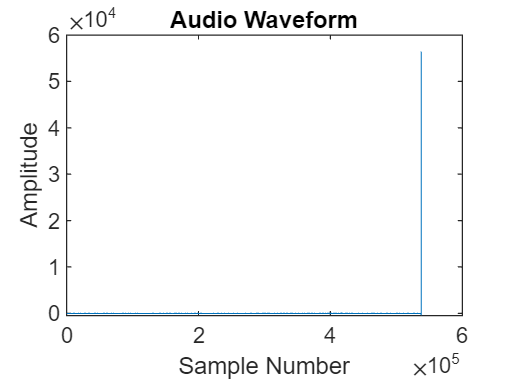

figure;
plot(reconstructed_signal_DaS_real);
xlabel('Sample Number');
ylabel('Amplitude');
title('Audio Waveform');

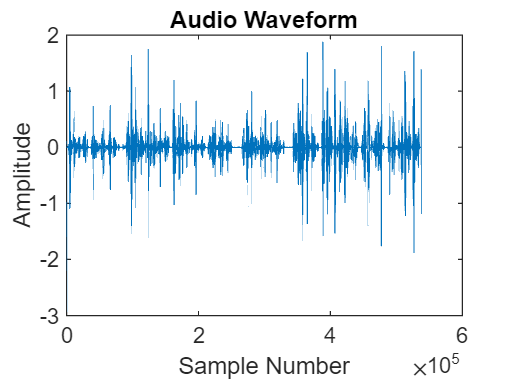


figure;
plot(reconstructed_signal_MVDR_real);
xlabel('Sample Number');
ylabel('Amplitude');
title('Audio Waveform');

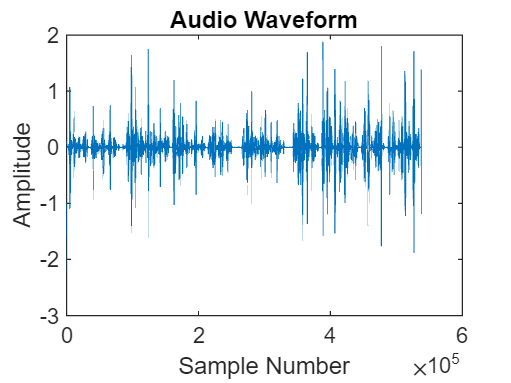


figure;
plot(reconstructed_signal_MCW_real);
xlabel('Sample Number');
ylabel('Amplitude');
title('Audio Waveform');

mic_signals{1} = mic_signals{1}(1:length(reconstructed_signal_DaS_real));
mic_signals{2} = mic_signals{2}(1:length(reconstructed_signal_DaS_real));
mic_signals{3} = mic_signals{3}(1:length(reconstructed_signal_DaS_real));
mic_signals{4} = mic_signals{4}(1:length(reconstructed_signal_DaS_real));


mic_noise{1} = mic_noise{1}(1:length(reconstructed_signal_DaS_real));
mic_noise{2} = mic_noise{2}(1:length(reconstructed_signal_DaS_real));
mic_noise{3} = mic_noise{3}(1:length(reconstructed_signal_DaS_real));
mic_noise{4} = mic_noise{4}(1:length(reconstructed_signal_DaS_real));

%Stoi_DaS = stoi(reconstructed_signal_DaS_real, clean_speech_2_short, fs);
clean_speech_2_short = clean_speech_2(1:length(mic_signals{1}));
SNR_test1 = 20*log10(norm(mic_signals{1})/norm(mic_signals{1}-clean_speech_2_short));
SNR_test2 = 20*log10(norm(mic_signals{2})/norm(mic_signals{2}-clean_speech_2_short));
SNR_test3 = 20*log10(norm(mic_signals{3})/norm(mic_signals{3}-clean_speech_2_short));
SNR_test4 = 20*log10(norm(mic_signals{4})/norm(mic_signals{4}-clean_speech_2_short));

Stoi_test1 = stoi(clean_speech_2_short, mic_signals{1}, fs);
Stoi_test2 = stoi(clean_speech_2_short, mic_signals{2}, fs);
Stoi_test3 = stoi(clean_speech_2_short, mic_signals{3}, fs);
Stoi_test4 = stoi(clean_speech_2_short, mic_signals{4}, fs);

reconstructed_signal_DaS_real_normalized = reconstructed_signal_DaS_real / max(abs(reconstructed_signal_DaS_real));
reconstructed_signal_MVDR_real_normalized = reconstructed_signal_MVDR_real / max(abs(reconstructed_signal_MVDR_real));
reconstructed_signal_MCW_real_normalized = reconstructed_signal_MCW_real / max(abs(reconstructed_signal_MCW_real));

sound(reconstructed_signal_DaS_real_normalized, fs);

sound(reconstructed_signal_MVDR_real_normalized, fs);

sound(reconstructed_signal_MCW_real_normalized, fs);

clear sound;

Stoi_DaS = stoi(clean_speech_2_short, reconstructed_signal_DaS_real,fs);
SNR_DaS = 20*log10(norm(reconstructed_signal_DaS_real_normalized)/norm(reconstructed_signal_DaS_real_normalized-clean_speech_2_short));

Stoi_MVDR = stoi(clean_speech_2_short, reconstructed_signal_MVDR_real,fs);
SNR_MVDR = 20*log10(norm(reconstructed_signal_MVDR_real_normalized)/norm(reconstructed_signal_MVDR_real_normalized-clean_speech_2_short));

Stoi_MCW = stoi(clean_speech_2_short, reconstructed_signal_MCW_real, fs);
SNR_MCW = 20*log10(norm(reconstructed_signal_MCW_real_normalized)/norm(reconstructed_signal_MCW_real_normalized-clean_speech_2_short));

%load handel.mat
%
%filename = 'Waveform_mic4.wav';
%audiowrite(filename,mic_signals{4},fs);